# Model Fidelity Considerations for Power Electronic Switching

Copyright © 2025, The MathWorks, Inc.

## Introduction

This document provides considerations for changing model fidelity of power electronic switching architectures. For demonstration, a half-bridge is considered, but the considerations apply to more complex topologies, such as three-phase two-level. Please refer to the Power Converters sub-library in the Support Library to see other topologies. 

To enable benchmarking for each of the fidelity levels considered, Ts = 1e-6s and Partitioning Solver : Robust was selected as the Local Solver. Note that you may see longer simulation times for average-switch with diodes compared to linear-switch with anti-parallel basic diodes, but the average-switch can be used with subcycle averaged inputs where appropriate, enabling a larger time-step to be used.

## Average-Value

*Half-bridge model: One controlled voltage source*

*Gate input: Modulation wave*

The lowest fidelity is an average-value voltage-source converter, where the input is the modulation wave. The AC voltage is calculated by multiplying DC voltage with an appropriately scaled modulation wave. DC current is then calculated by multiplying AC current by the scaled modulation wave.

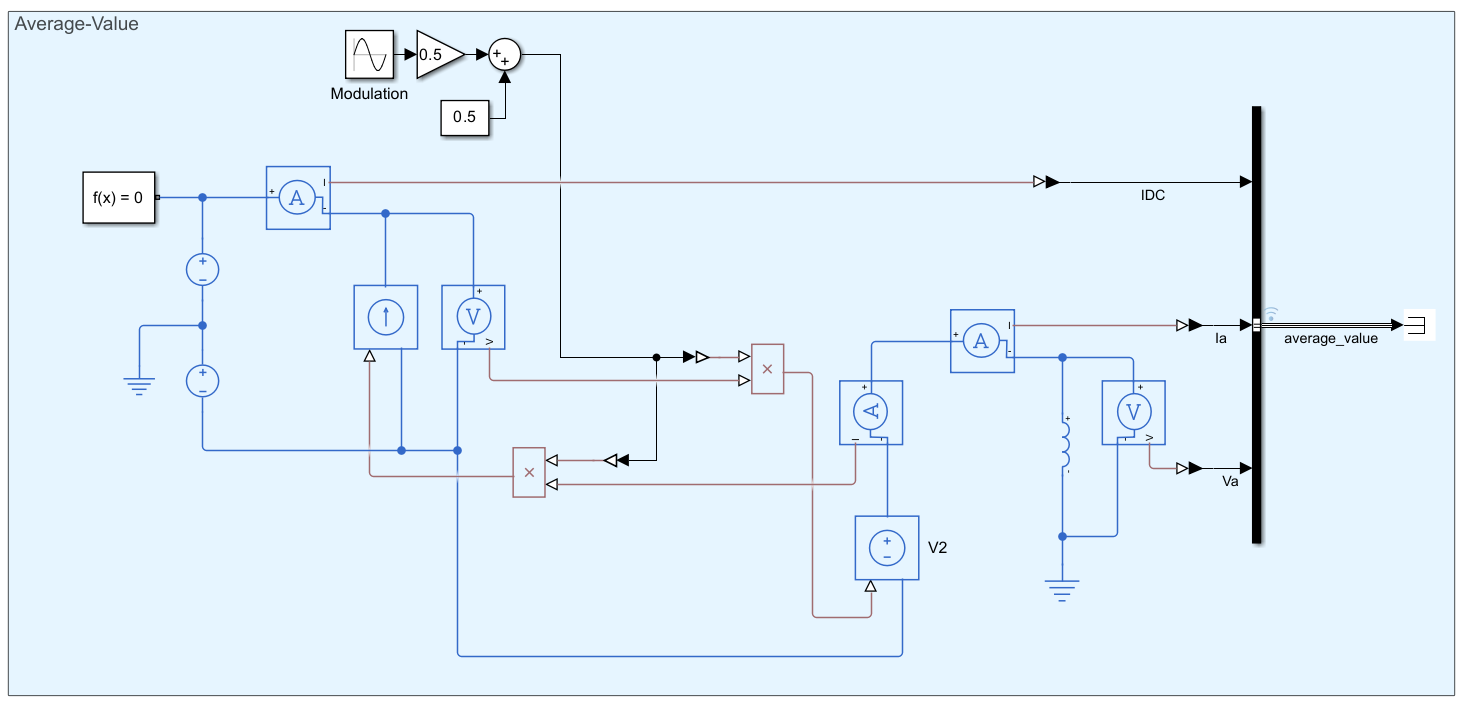

mdl = 'a_half_bridge_average_value';
open_system(mdl)
set_param(mdl,'SimulationMode','accelerator');
set_param(mdl,'FastRestart','on');
tic;sim(mdl,'StopTime','0');t_comp_average_value = toc

t_comp_average_value = 3.5361

tic;sim(mdl,'StopTime','2');t_sim_average_value = toc

t_sim_average_value = 13.4183

set_param(mdl,'FastRestart','off');


## Average-Value with Diode

*Half-bridge model: Two controlled voltage sources in series with two diodes*

*Gate input: Modulation wave*

With this fidelity, we include diodes in our topology and the input is the modulation wave. The reason we include diodes, is so that we have the option to open the controllable switches (by setting voltage sources to zero) and be left with a diode bridge topology. This fidelity is valuable where we want to avoid short circuiting our AC output when we set the voltage sources to zero. When we set the *open* input to 1, all voltage sources are set to zero and the diode bridge is fully connected to the DC lines. The figure below shows a representation of the conduction paths for this level of fidelity when we have an active modulation wave.

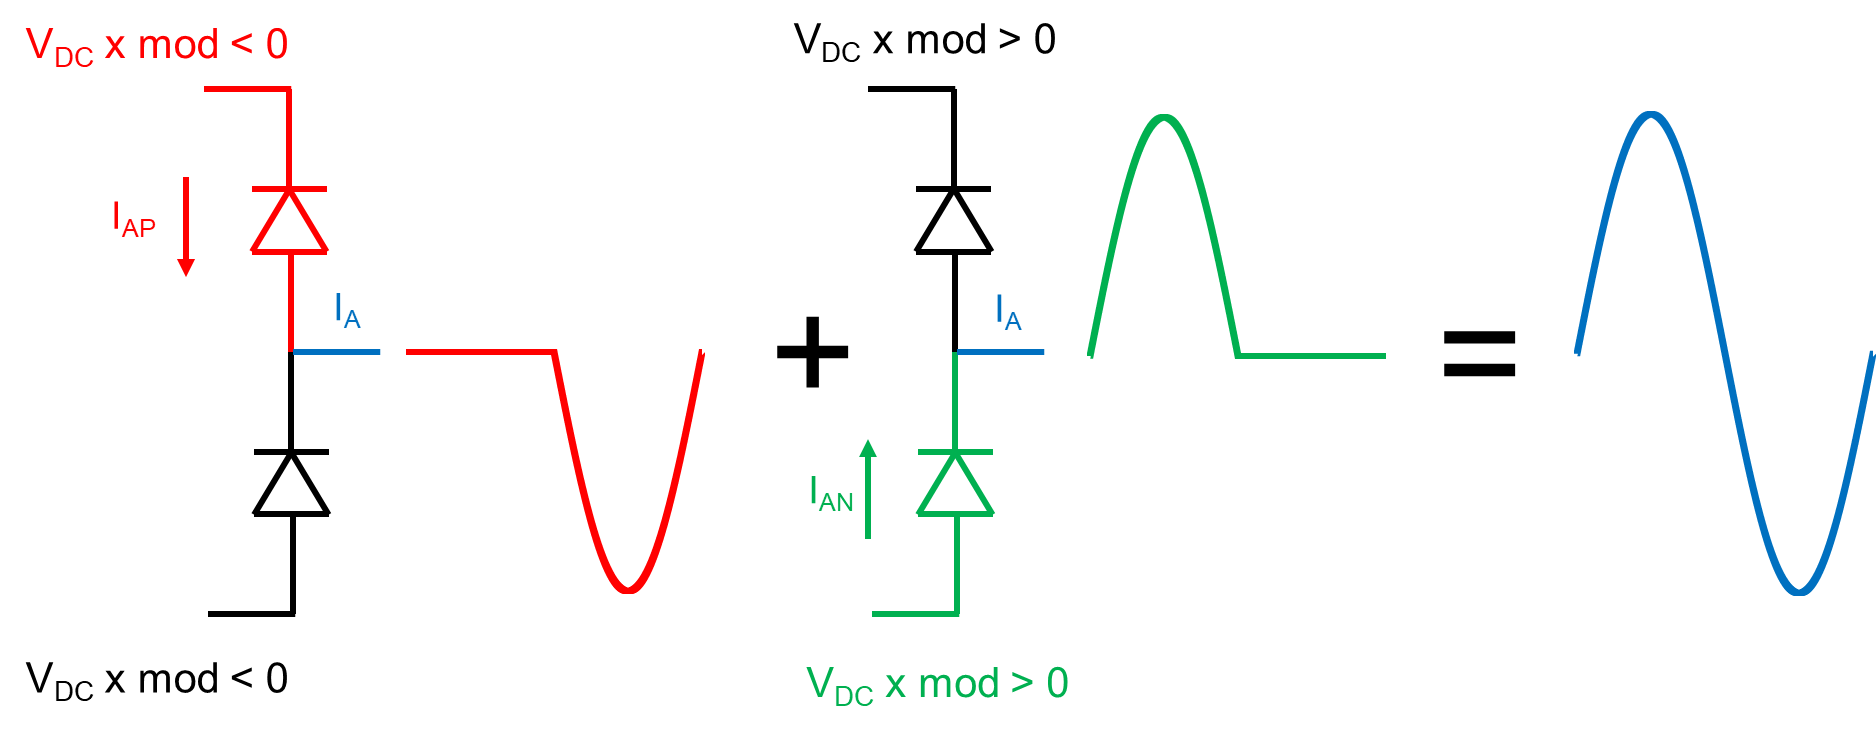

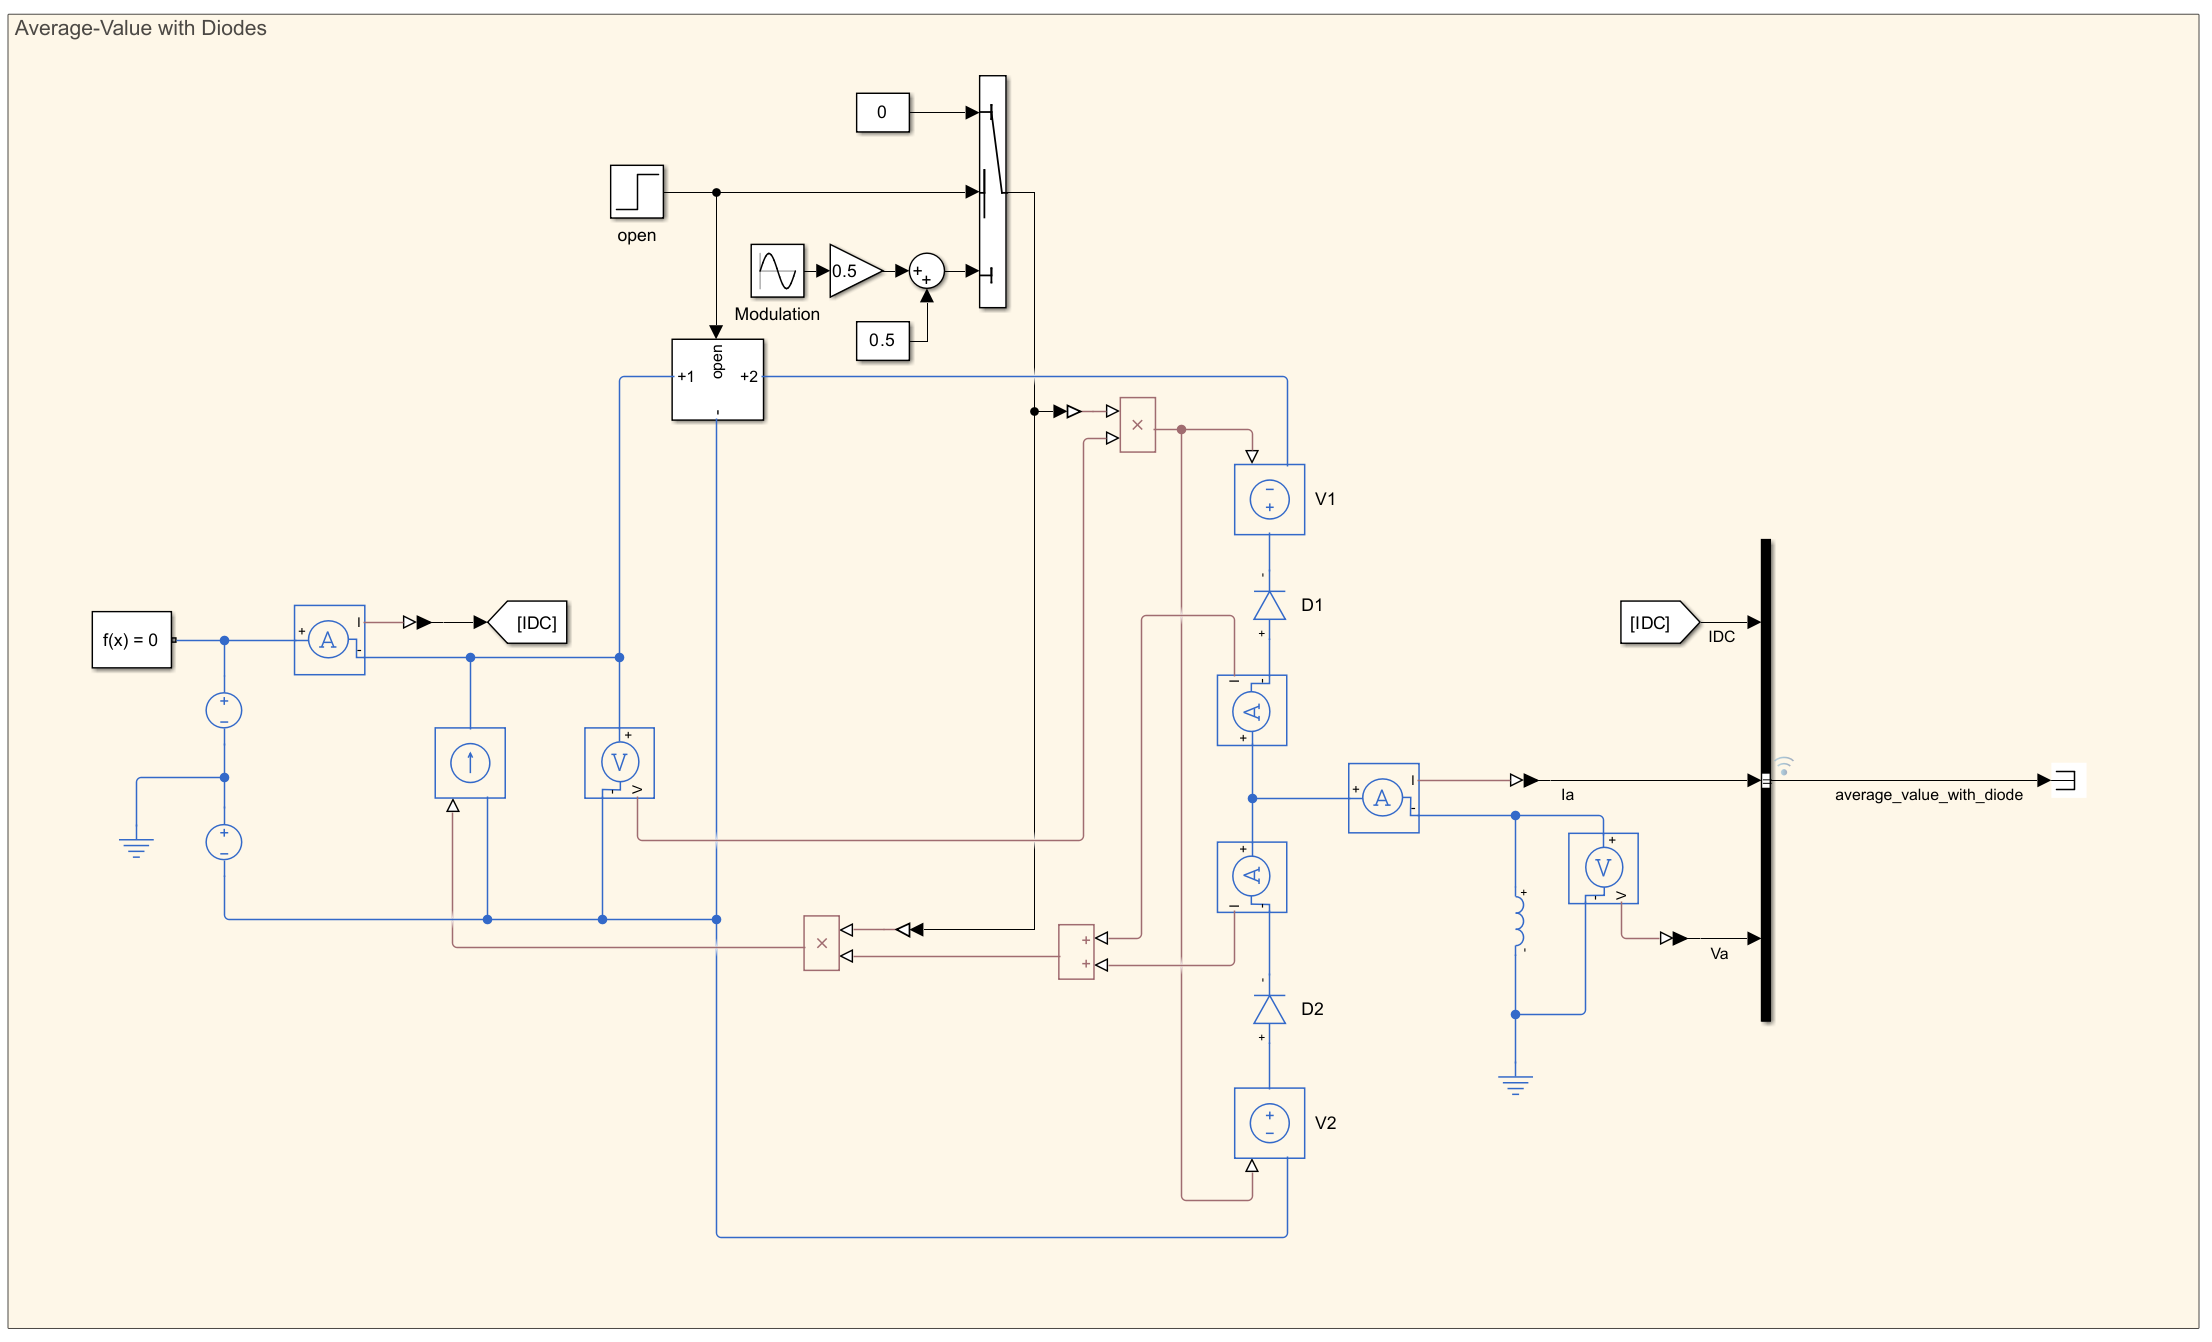

mdl = 'b_half_bridge_average_value_with_diode';
open_system(mdl)
set_param(mdl,'SimulationMode','accelerator');
set_param(mdl,'FastRestart','on');
tic;sim(mdl,'StopTime','0');t_comp_average_value_with_diode = toc

t_comp_average_value_with_diode = 4.1821

tic;sim(mdl,'StopTime','2');t_sim_average_value_with_diode = toc

t_sim_average_value_with_diode = 16.8310

set_param(mdl,'FastRestart','off');


## Average-Switch with Diode

*Half-bridge model: Two controlled voltage sources in series with two diodes*

*Gate input: PWM signals*

With this fidelity, we include diodes in our topology and the input is the PWM signals. The physical architecture is the same as the average-value with diode architecture, but we can now emulate the effect of PWM switching on the controlled voltage sources. We can either directly use the PWM signal, or modify it using subcycle averaging. Note that only the PWM signal for the positive arm is needed. When we set the *open* input to 1, all voltage sources are set to zero and the diode bridge is fully connected to the DC lines. Low-pass filters are included in measurement signals to provide comparison to the average-value results.

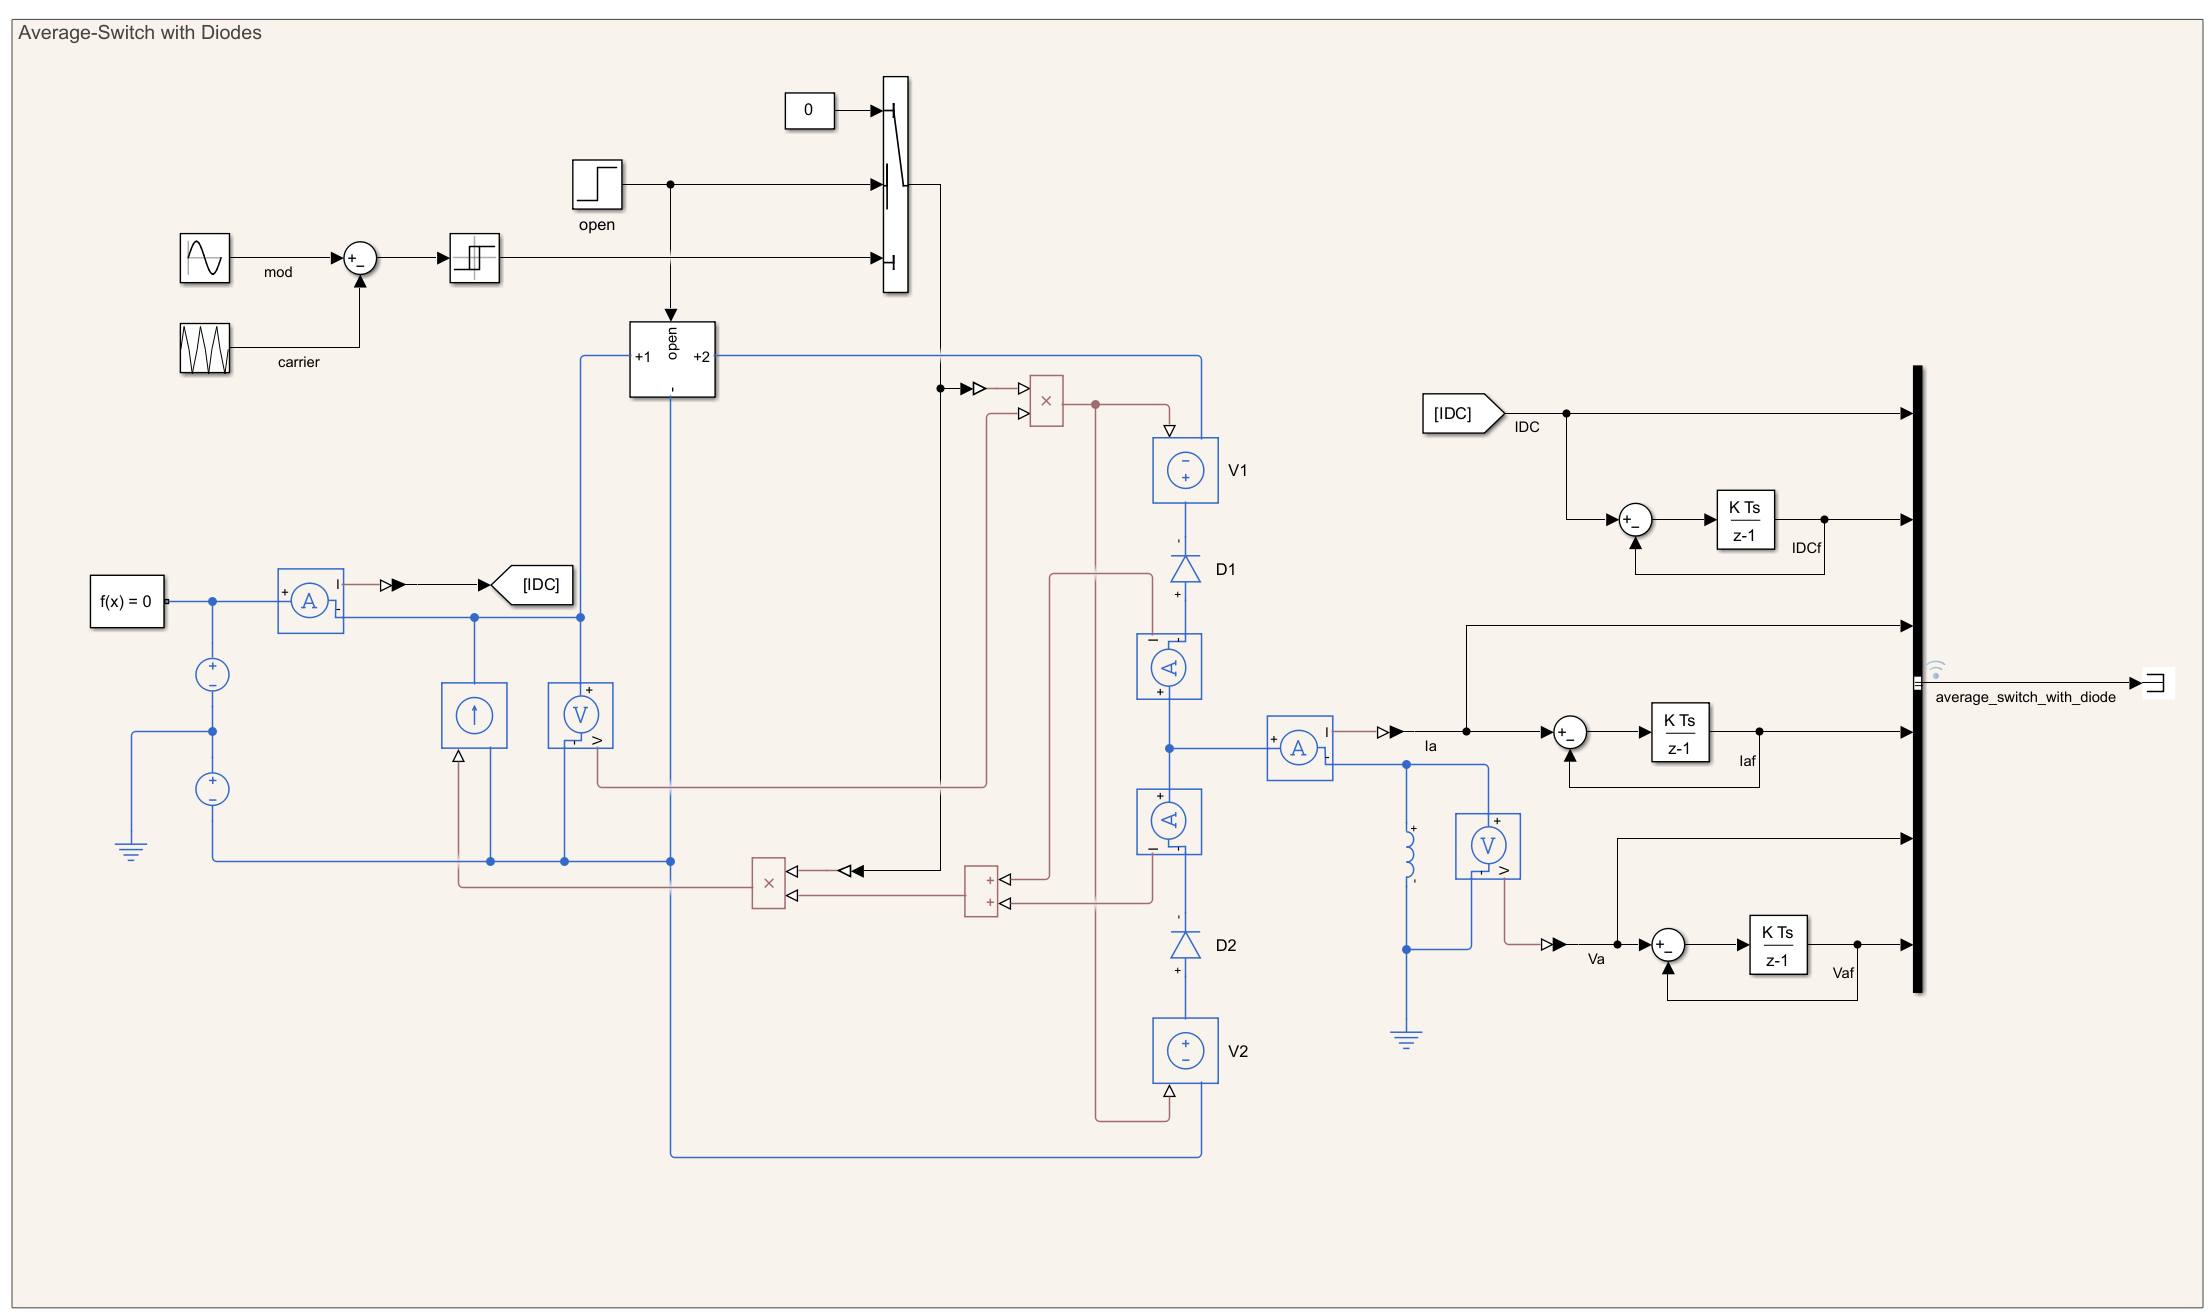

mdl = 'c_half_bridge_average_switch_with_diode';
open_system(mdl)
set_param(mdl,'SimulationMode','accelerator');
set_param(mdl,'FastRestart','on');
tic;sim(mdl,'StopTime','0');t_comp_average_switch_with_diode = toc

t_comp_average_switch_with_diode = 3.5157

tic;sim(mdl,'StopTime','2');t_sim_average_switch_with_diode = toc

t_sim_average_switch_with_diode = 19.2153

set_param(mdl,'FastRestart','off');

## Linear-Switch with Basic Diode

*Half-bridge model: Two linear switches with anti-parallel basic diodes (forward voltage fixed at 0V)*

*Gate input: PWM signals*

With this fidelity, we model fully controllable linear switches with anti-parallel diodes. The input is the PWM signals. With this fidelity, the diode forward voltage is fixed at 0V. Note however that the When switches are set to off (gate inputs equal to 0), we are left with a diode bridge. Low-pass filters are included in measurement signals to provide comparison to the average-value results.

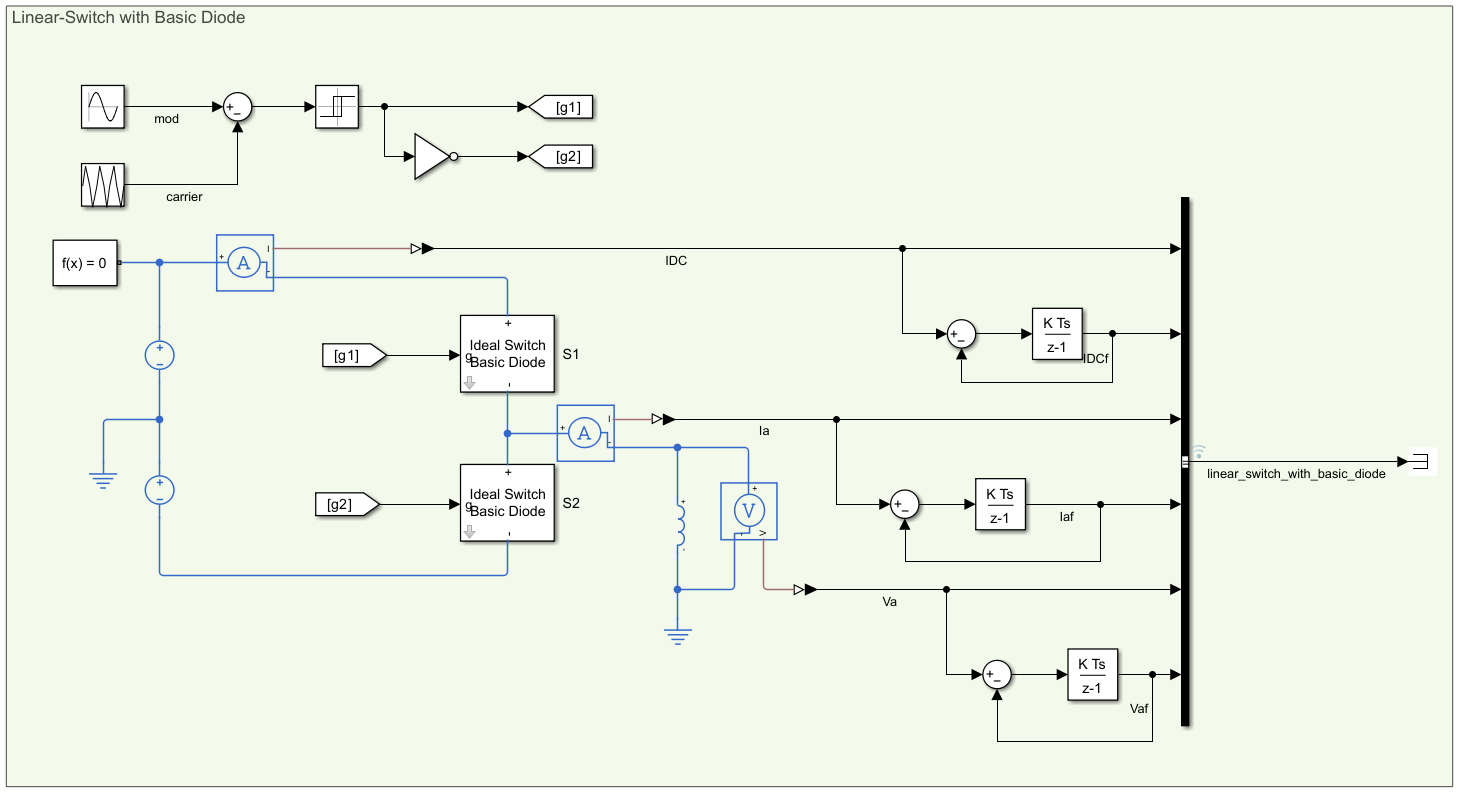

mdl = 'd_half_bridge_linear_switch_with_basic_diode';
open_system(mdl)
set_param(mdl,'SimulationMode','accelerator');
set_param(mdl,'FastRestart','on');
tic;sim(mdl,'StopTime','0');t_comp_linear_switch_with_basic_diode = toc

t_comp_linear_switch_with_basic_diode = 1.8888

tic;sim(mdl,'StopTime','2');t_sim_linear_switch_with_basic_diode = toc

t_sim_linear_switch_with_basic_diode = 17.0334

set_param(mdl,'FastRestart','off');

## Linear-Switch with Diode

*Half-bridge model: Two linear switches with anti-parallel diodes*

*Gate input: PWM signals*

With this fidelity, we model fully controllable linear switches with anti-parallel diodes. The input is the PWM signals. This is the highest level of fidelity that we cover in this report. Note however that the When switches are set to off (gate inputs equal to 0), we are left with a diode bridge. Low-pass filters are included in measurement signals to provide comparison to the average-value results.

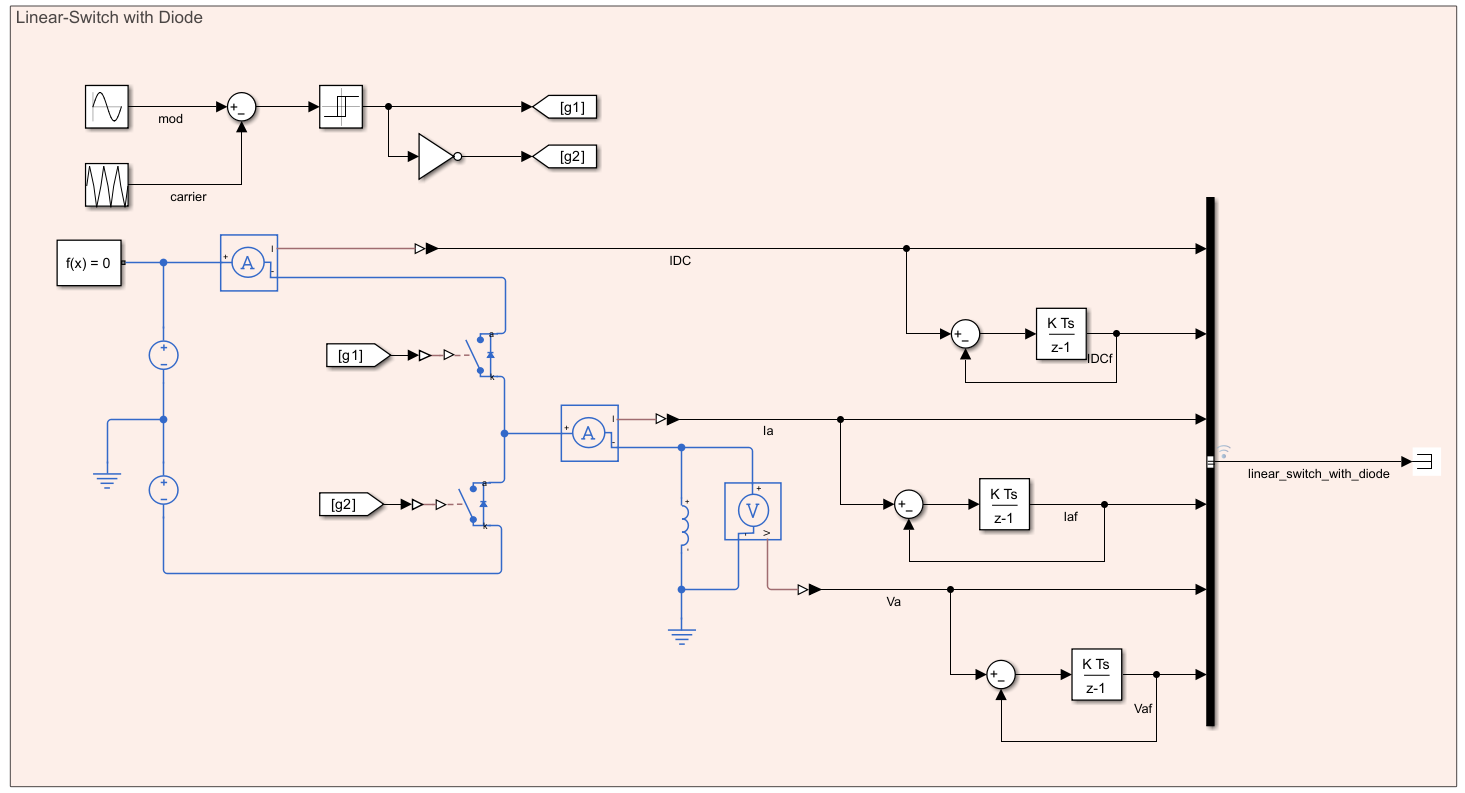

mdl = 'e_half_bridge_linear_switch_with_diode';
open_system(mdl)
set_param(mdl,'SimulationMode','accelerator');
set_param(mdl,'FastRestart','on');
tic;sim(mdl,'StopTime','0');t_comp_linear_switch_with_diode = toc

t_comp_linear_switch_with_diode = 2.7053

tic;sim(mdl,'StopTime','2');t_sim_linear_switch_with_diode = toc

t_sim_linear_switch_with_diode = 18.4137

set_param(mdl,'FastRestart','off');

## Simulation Results

Explore the simulation results using the Simulation Data Inspector.

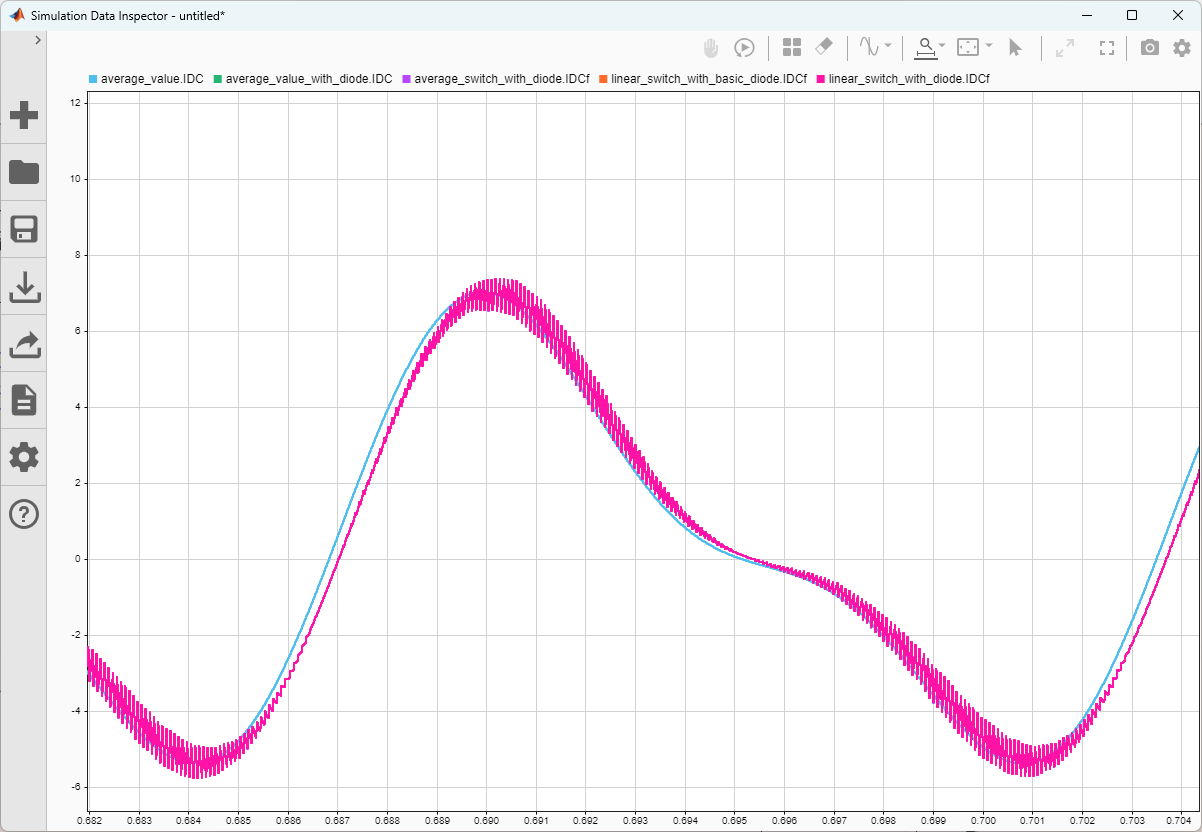

## **Reference**

For more information on sub-cycle averaging,

J. Allmeling and N. Felderer, "Sub-cycle average models with integrated diodes for real-time simulation of power converters," 2017 IEEE Southern Power Electronics Conference (SPEC), Puerto Varas, Chile, 2017, pp. 1-6, doi: 10.1109/SPEC.2017.8333566. keywords: {Switches;Integrated circuit modeling;Computational modeling;Choppers (circuits);Real-time systems;Mathematical model},

END OF DOCUMENT